% Практическое занятие №14
% Макроэкономическое равновесие в краткосрочном периоде:
% модель IS-LM

% Объект моделирования - закрытая экономика (NX=0)
% Модель IS
% 𝒀 = 𝑪(𝒀 − 𝑻) + 𝑰(𝒓) + 𝑮
% => Y - C - G = I(r) => S(Y) = I (r)
% Задание №1
% Получите алгебраическое выражение 𝒀 = 𝑪(𝒀 − 𝑻) + 𝑰(𝒓) + 𝑮 для кривой 𝑰𝑺 в
% предположении линейности функции потребления и инвестиций.
syms Y C I G T r a0 a1 b0 b1
C=a0+a1*(Y-T );
I=b0+b1*r;

eqn1=Y-C-I-G;
Y=expand(solve(eqn1,Y ))

$$Y = \frac{T\,a_{1}}{a_{1}-1}-\frac{a_{0}}{a_{1}-1}-\frac{b_{0}}{a_{1}-1}-\frac{G}{a_{1}-1}-\frac{b_{1}\,r}{a_{1}-1}$$


%Y=(a0+b0)/(1-a1)+b1/(1-a1)*r+1/(1-a1)*G+(-a1/(1-a1))*T

%Модель IS показывает все комбинации национального дохода Y и процентной
%ставки r(Y,r), при которых устанавливается равновесие на рынке товаров и
%услуг и соответсвенно финансовом рынке в закрытой экономике S=I
% S(Y) = I (r)

% Задание 2
syms Y r M p c1 c2

% Модель LM
% Тождество равновесия на денежном рынке:
% M/p = c1*Y + c2*r, c1>0, c2<0

eqn2 = M/p - c1*Y - c2*r;
r = expand(solve(eqn2,r))

$$r = \frac{M}{c_{2}\,p}-\frac{Y\,c_{1}}{c_{2}}$$

% r = -c1/c2*Y + 1/c2*M/p

%  или
Y = expand(solve(eqn2,Y))

$$Y = \frac{M}{c_{1}\,p}-\frac{c_{2}\,r}{c_{1}}$$

% Y = -c2/c1*r + 1/c1*M/p
% Модель LM позволяет определять все комбинации (Y,r), которые обеспечивают
% равновесие на денежном рынке


% Задание 3
% Модель совокупного спроса IS-LM
syms Y r 

eqn3 = Y-(a0+b0)/(1-a1)-b1/(1-a1)*(-c1/c2*Y + 1/c2*M/p)-1/(1-a1)*G-(-a1/(1-a1))*T;
Y = solve(eqn3,Y)

$$Y = \frac{\frac{a_{0}+b_{0}}{a_{1}-1}+\frac{G}{a_{1}-1}-\frac{T\,a_{1}}{a_{1}-1}+\frac{M\,b_{1}}{c_{2}\,p\,\left(a_{1}-1\right)}}{\frac{b_{1}\,c_{1}}{c_{2}\,\left(a_{1}-1\right)}-1}$$

Y_AD = Y;
% Полученное выражение соответсвует модели совокупного спроса.
% Модель пол=зволяет изучать влияние бюджетно-налоговой (T,G) и денежной
% (монетарной) политики на величину национального дохода (совокупного
% спроса)

% Задание 4
syms Y G T r
a0 = 200; a1 = 0.75; b0 = 200; b1 = -25; G = 100; T = 100;
% Модель IS
Y=(a0+b0)/(1-a1)+b1/(1-a1)*r+1/(1-a1)*G+(-a1/(1-a1))*T

$$Y = 1700-100\,r$$

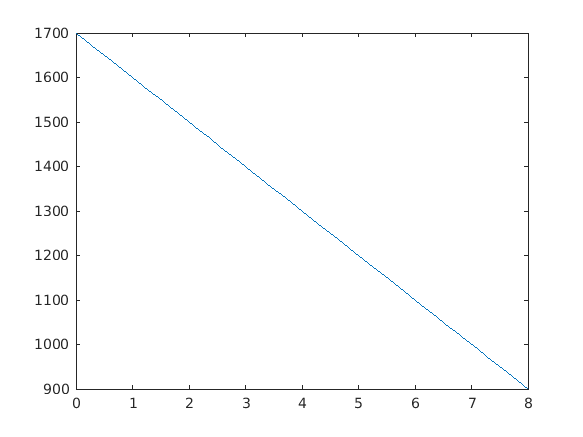


fplot(Y,[0 8])
hold on 

% Модель LM
syms Y r 
M = 1000;  p = 2; c1 = 1; c2 = -100;
Y = -c2/c1*r + 1/c1*M/p

$$Y = 100\,r+500$$

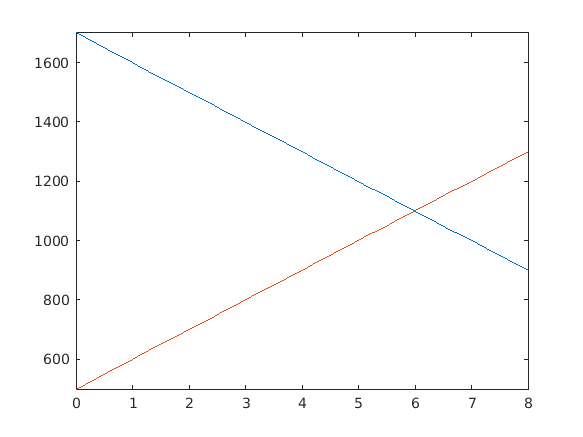


fplot(Y, [0 8])
hold off


syms Y r 
Eq = solve(Y == 1700-100*r, Y == 100*r+500, [Y r])

Eq = struct with fields:
    Y: [1×1 sym]
    r: [1×1 sym]


Eq.Y

$$ans = 1100$$

Eq.r

$$ans = 6$$

% Равновесие 2
% Модель IS
syms Y r
a0 = 200; a1 = 0.75; b0 = 200; b1 = -25; G = 150; T = 100;
Y=(a0+b0)/(1-a1)+b1/(1-a1)*r+1/(1-a1)*G+(-a1/(1-a1))*T

$$Y = 1900-100\,r$$


% Модель LM
syms Y r 
M = 1200;  p = 2; c1 = 1; c2 = -100;
Y = -c2/c1*r + 1/c1*M/p

$$Y = 100\,r+600$$


% Равновесие:
syms Y r 
Eq = solve(Y == 1900-100*r, Y == 100*r+600, [Y r])

Eq = struct with fields:
    Y: [1×1 sym]
    r: [1×1 sym]


Eq.Y

$$ans = 1250$$

Eq.r

$$ans = \frac{13}{2}$$


vpa(Eq.r,3)

$$ans = 6.5$$

% Равновесие 2: (Y = 1250; r = 6.5)
% Увеличение государственных закупок на 50 денежных единиц и увеличение
% денежной массы в экономике (дополнительная денежная эмиссия) на 200
% денежных единиц привели к росту национального дохода на 150 единиц и
% росту ставки поцента на 0.5%.

% Урвнение совокупного спроса (по данным задачи)
syms G T M p
a0 = 200; a1 = 0.75; b0 = 200; b1 = -25;
Y = subs(Y_AD)

$$Y = 2\,G-\frac{3\,T}{2}+\frac{M}{2\,p}+800$$


% Равновесие 1
T = 100; G = 100; M = 1000; p = 2;
subs(Y)

$$ans = 1100$$


% Равновесие 2
T = 130; G = 90; M = 1000; p = 2;
subs(Y)

$$ans = 1035$$

% Самостоятельное задание (Вариант 17)
M = 1000; p = 2;
% Модель IS
syms Y r
a0 = 79; a1 = 0.58; b0 = 180; b1 = 11; G = 58; T = 116;
Y_IS=(a0+b0)/(1-a1)+b1/(1-a1)*r+1/(1-a1)*G+(-a1/(1-a1))*T

$$Y\_IS = \frac{550\,r}{21}+\frac{4162}{7}$$


% Модель LM
syms Y r 
c1 = 2; c2 = -900;
Y_LM = -c2/c1*r + 1/c1*M/p

$$Y\_LM = 450\,r+250$$


% Модель IS-LM (совокупного спроса):
syms Y G T r
a0 = 79; a1 = 0.58; b0 = 180; b1 = 11; G = 58; T = 116;
% IS
Y=(a0+b0)/(1-a1)+b1/(1-a1)*r+1/(1-a1)*G+(-a1/(1-a1))*T

$$Y = \frac{550\,r}{21}+\frac{4162}{7}$$

% Y = 550*r/21 + 4162/7

% LM
syms Y r 
M = 1000;  p = 2; c1 = 2; c2 = -900;
Y = -c2/c1*r + 1/c1*M/p

$$Y = 450\,r+250$$

% Y = 450*r+250

% Равновесие 1
syms Y r 
Eq1 = solve(Y == 550*r/21 + 4162/7, Y == 450*r+250, [Y r])

Eq1 = struct with fields:
    Y: [1×1 sym]
    r: [1×1 sym]


Eq1.Y

$$ans = \frac{54812}{89}$$

Eq.r

$$ans = \frac{13}{2}$$


% Равновесие 2
syms Y r 
T = 127; G = 67; M = 1200; p = 2;
% IS
Y=(a0+b0)/(1-a1)+b1/(1-a1)*r+1/(1-a1)*G+(-a1/(1-a1))*T

$$Y = \frac{550\,r}{21}+\frac{12617}{21}$$

% Y = 550*r/21 + 12617/21

% LM
syms Y r 
Y = -c2/c1*r + 1/c1*M/p

$$Y = 450\,r+300$$

% Y = 450*r+

syms Y r 
Eq2 = solve(Y == 550*r/21+12617/21, Y == 450*r+300, [Y r])

Eq2 = struct with fields:
    Y: [1×1 sym]
    r: [1×1 sym]


Eq2.Y

$$ans = \frac{110253}{178}$$

Eq2.r

$$ans = \frac{6317}{8900}$$